

graphSet;

repertoire = './'; % Chemin d'acces au code compile (NB: enlever le ./ sous Windows)
executable = 'Exercice7'; % Nom de l'executable (NB: ajouter .exe sous Windows)
input = '7_3_b.in'; % Nom du fichier d'entree de base


 nsimul = 3;
xa = linspace(200000,360000,nsimul);

xb = 370000* ones(size(xa));

h_ocean = 8e3;
h_recif = 20;
xc = 430e3;
xd = 600e3;
g = 9.81;

paramstr = 'xa';
param = xa;

output = cell(1, nsimul); % Tableau de cellules contenant le nom des fichiers de sortie
for i = 1:nsimul
    output{i} = [paramstr, '=', num2str(xa(i) )];
    % Execution du programme en lui envoyant la valeur a scanner en argument
    cmd = sprintf('wsl %s%s %s xa=%.15g xb=%.15g  output=%s', repertoire, executable, input, xa(i),xb(i),output{i});
    disp(cmd);
    system(cmd);
end

wsl ./Exercice7 7_3_b.in xa=200000 xb=370000  output=xa=200000


	tfin=20000
	L=800000
	Npoints=2000
	CFL=1
	type_u2=tsunami
	g=9.81
	h_ocean=8000
	h_recif=20
	xa=200000
	xb=370000
	xc=430000
	xd=600000
400.2
1.42856
	ecrire_f=1
	schema=B
	cb_gauche=harmonique
	cb_droit=sortie
	A=1
	omega=0.007
	output=xa=200000
	n_stride=1


wsl ./Exercice7 7_3_b.in xa=280000 xb=370000  output=xa=280000


	tfin=20000
	L=800000
	Npoints=2000
	CFL=1
	type_u2=tsunami
	g=9.81
	h_ocean=8000
	h_recif=20
	xa=280000
	xb=370000
	xc=430000
	xd=600000
400.2
1.42856
	ecrire_f=1
	schema=B
	cb_gauche=harmonique
	cb_droit=sortie
	A=1
	omega=0.007
	output=xa=280000
	n_stride=1


wsl ./Exercice7 7_3_b.in xa=360000 xb=370000  output=xa=360000


	tfin=20000
	L=800000
	Npoints=2000
	CFL=1
	type_u2=tsunami
	g=9.81
	h_ocean=8000
	h_recif=20
	xa=360000
	xb=370000
	xc=430000
	xd=600000
400.2
1.42856
	ecrire_f=1
	schema=B
	cb_gauche=harmonique
	cb_droit=sortie
	A=1
	omega=0.007
	output=xa=360000
	n_stride=1


peak = 7

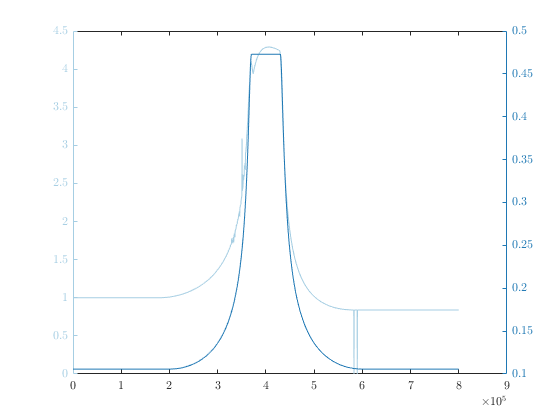

peak = 7

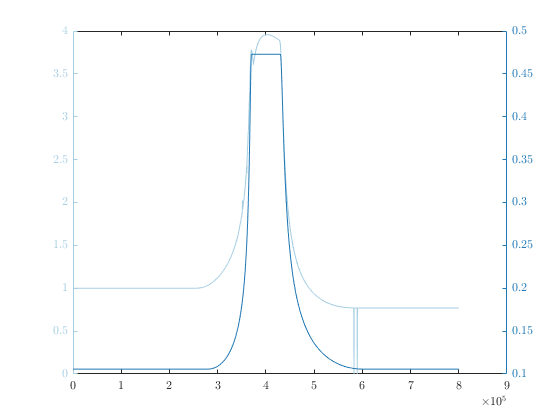

peak = 7

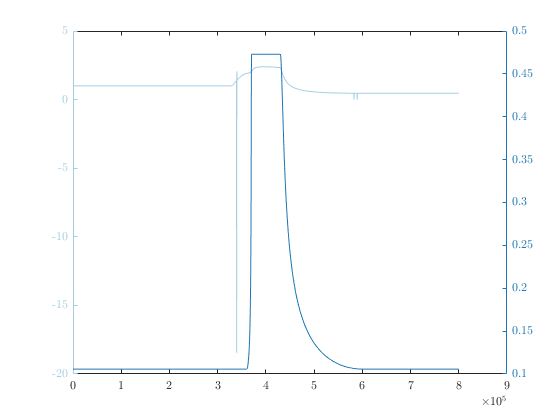

for i = 1:nsimul

fichier = output{i};
data = load([fichier,'_u.out']);
x = data(:,1);
u = data(:,2);
data = load([fichier,'_E.out']);
t = data(:,1);
E = data(:,2);
data = load([fichier,'_f.out']);
f = data(:,2:end);


h = zeros(size(x,1),1);
h(x <= xa(i) | x >= xd) = h_ocean;
h(xa(i) < x & x < xb(i)) = h_ocean + (h_recif - h_ocean) * ...
                     sin(0.5 * pi * (x(xa(i) < x & x < xb(i)) - xa(i)) / (xb(i) - xa(i))).^2;
h(xb(i) < x & x <= xc) = h_recif;
h(xc < x & x < xd) = h_recif - (h_recif - h_ocean) * ...
                     sin(0.5 * pi * (xc - x(xc < x & x < xd)) / (xc - xd)).^2;

peak = 3; % choice of the peak to follow
fr = 20; % range of points for interpolation
lim = 0.1; % level above or below 0 for peak detection
[aA,uA,tmaxA] = maxWave2(x,t,f,peak,fr,lim);
figure
yyaxis left
plot(x,aA)
yyaxis right
plot(x,h.^(-0.25))
end